# EEE3548 Exercise #3

## [2019142047] [JeonMinsu]

#### Q1. Define the OTF of  an ideal imaging system, whose cut-off frequency is $k_c$ = 8 cycles per mm. Assume that a pixel is 0.005mm (N = 256). 

#### Plot the PSF of the system (intensity). What is the resolution of this camera defined by 1) the FWHM (Abbe's criterion) and 2) the Rayleigh's criterion? 

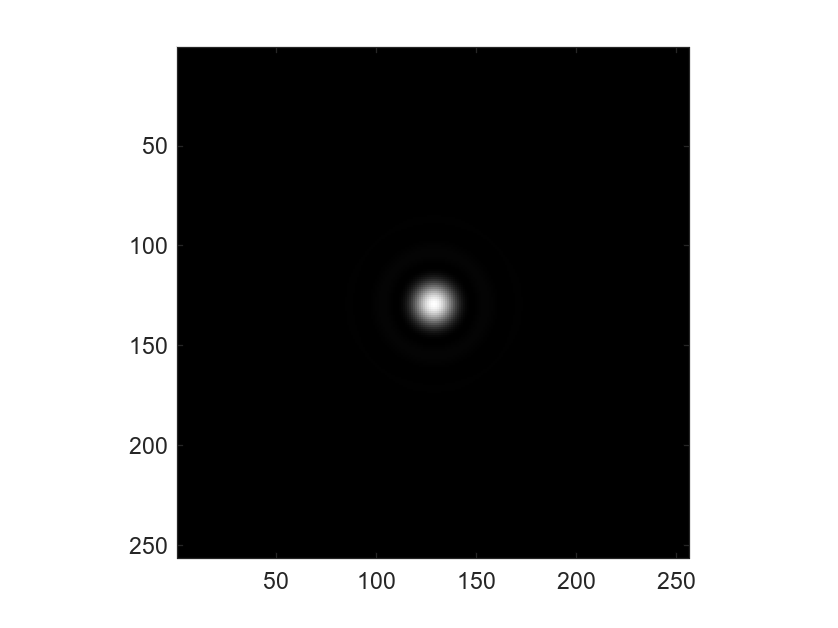

N = 256;            % N = 256
psize = 0.005;      % pixel is 0.005mm

x = linspace(-1/2, 1/2, N) * N/psize;  % x-axis
y = linspace(-1/2, 1/2, N) * N/psize;  % y-axis
[k_x,k_y] = meshgrid(x,y);


k_c = 8/psize;                         % cut-off frequency is 8

otf = zeros(N,N);
otf( k_x.^2 + k_y.^2 <= k_c^2 ) = 1;        % create ideal OTF
otf_real = ifftshift(ifft2(otf)); 
Intensity = abs(otf_real).^2;               % get intensity of OTf

imagesc(Intensity);axis image;colormap gray;   % show intensity of OTf

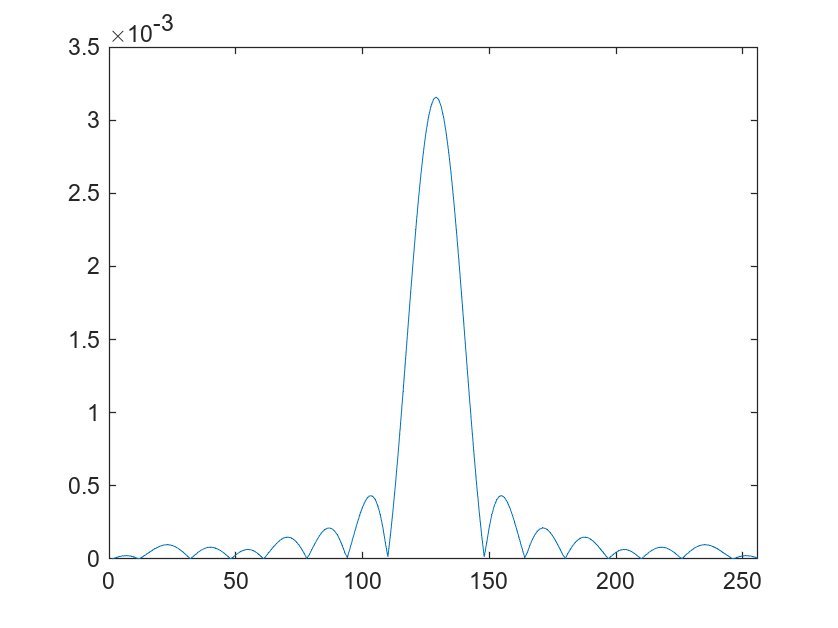

x = abs(otf_real( : , 128));       % get the line of y = 0
               
plot(abs(x)); xlim([0 N]);         % plot the psf

1) the FWHM (Abbe's criterion)

f_max = x(129);            
I = find(f_max*0.5 < x);    % find the half of max 
num = (129 - I(1))*2;       % abbe is 2*(distance between max and half of max)
abbe = num*psize

abbe = 0.1100

따라서, FWHM = 0.11이다.

2) the Rayleigh's criterion

n = 1:129;
I = find(x(n) > x(n+1) & x(n+1) < x(n+2));  % find the point of local minimum
num = (129 - I(length(I)));                 % rayleigh is (distance between max and max-nearest local minimum)
rayl = num*psize

rayl = 0.1000

따라서, Rayleigh's criterion = 0.1이다.

#### Q2. Download "1.4.07.tiff" from [https://sipi.usc.edu/database/download.php?vol=textures&img=1.4.07](https://sipi.usc.edu/database/download.php?vol=textures&img=1.4.07)

#### Load the image, plot the image and its Fourier spectrum.

#### Downsample the image by a factor of 10 (one out of every 10 samples), plot the image and its Fourier spectrum. What do you see?

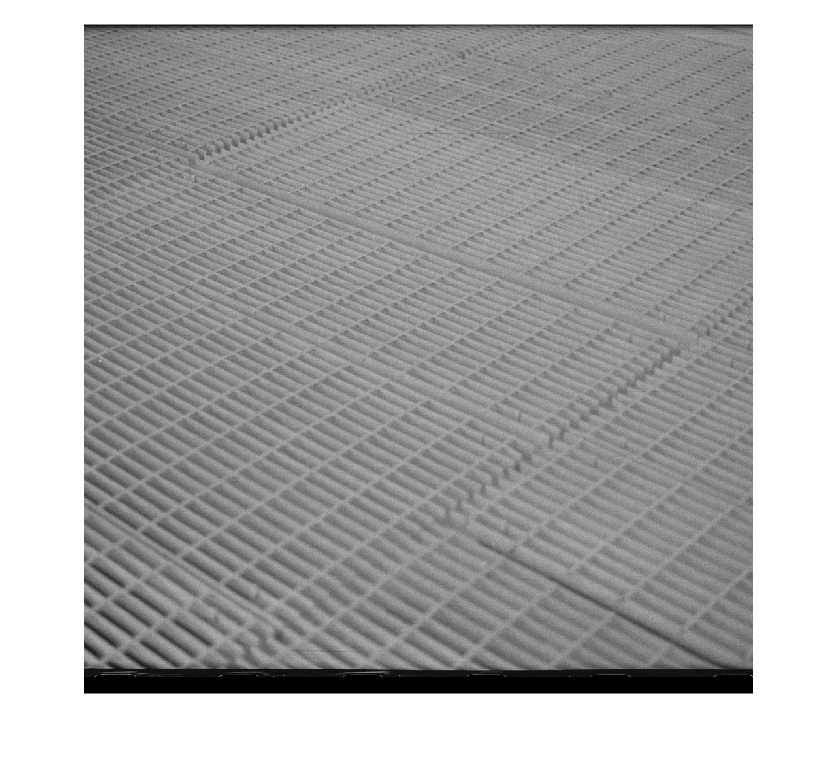

test_img = imread('1.4.07.tiff'); % read cameraman as test image
imshow(test_img);                 % show test image

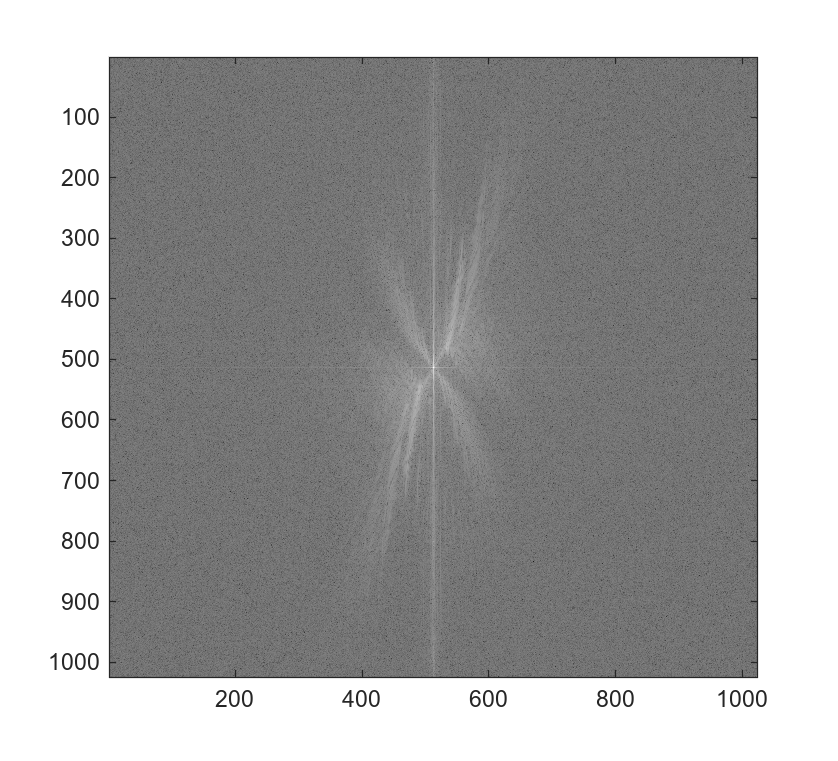

ftest_img = fftshift(fft2(test_img));       % fourier transform the test image
imagesc(log(abs(ftest_img)));               % show transformed test image

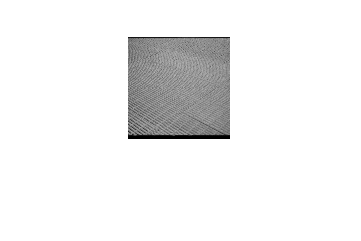

len = length(test_img);                   
down_img = test_img(1:10:len,1:10:len);     % Downsample the image by a factor of 10
imshow(down_img);                           % Show the downsampled image

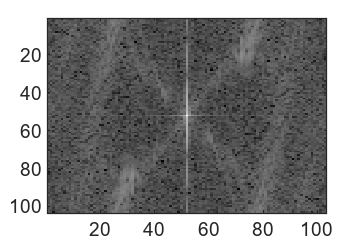

fdown_img = fftshift(fft2(down_img));       % fourier transform the downsampled image
imagesc(log(abs(fdown_img)));               % show transformed downsample image

Downsampling 을 크게 했기 때문에, aliasing이 나타나게 되고, 기존의 Frequenct domain과 비교하여, 기존의 형태에 새로운 값들이 추가된것처럼 나타나는것을 확인할 수 있다.

#### Q3. In your test image, add zero-mean white gaussian noise to change the SNR of the image. Use imnoise function (read its description) to choose appropriate value of noise variance. You need to install image processing toolbox of MATLAB. Plot the Fourier spectrum of the noisy images, explain what you see. 

noisy_img = imnoise(test_img,'gaussian');
fnoisy_img = fftshift(fft2(noisy_img));
log(abs(fnoisy_img))

ans =     9.7367   10.8452    9.8852    9.7016   10.6176    9.8224   10.3376   10.4928    9.7816   10.5692    8.5871    9.4622    9.7306   10.6232   10.4245   10.8346   10.0581    9.7026   10.7389    9.7435   10.1955   10.4864   10.4829   10.9090    9.2473    9.6427   10.4115   10.2362    9.9061    9.3683   10.0468   10.5582   10.9774    9.6601    9.8410   10.7554    9.8973   10.4962   10.6442    9.7503    9.9436    9.9160    9.8771   10.4864    9.8372   10.3982   10.1639   10.0321    9.6224    9.0249
    9.6740   10.5514   10.6704    9.7296    8.5551   10.6457    8.9304   10.9848   10.2532   10.0300   10.1573    9.8210    9.0617    9.0213    9.4174   10.8471   10.3401    9.7795   10.3380   10.3167   10.1237    8.9347    9.7502    9.8106    9.9233    9.3484    8.6910    9.3024    9.5064   10.1864   10.5947   10.3134   10.2635   10.6310    9.3981   10.3939   10.6443    9.7932    9.5374   10.4062    9.6400   10.1295    9.9788    9.9478   10.5372    9.7605   10.4510   10.7076   10.1558   

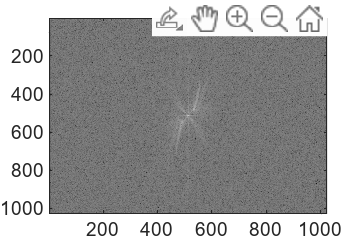

imagesc(log(abs(fnoisy_img)));

가우시안 노이즈의 영향으로, 전반적으로 높은 주파까지의 값들이 골고루 나타나게 된다. 이 때문에, Frequency Domain에서 상대적으로 Image 에 대한 형태가 Gaussian에 묻히게 되고(특히 값이 작은 high frequency), log scale에서 기존 Image의 frequency 성분들이 약하게 보이는것을 확인할 수 있다.